# **Functions definition and manipulation**

When a domain and a mesh are built, you can create and manipulate P0 and P1 functions defined on the mesh. 

P0 functions are constant in each mesh triangle.

P1 functions are continuous in the domain and linear in each triangle.

First build a domain and a mesh:

domain = Domain('square');
mesh = Mesh(domain,0.05);

building mesh
building mesh properties
done


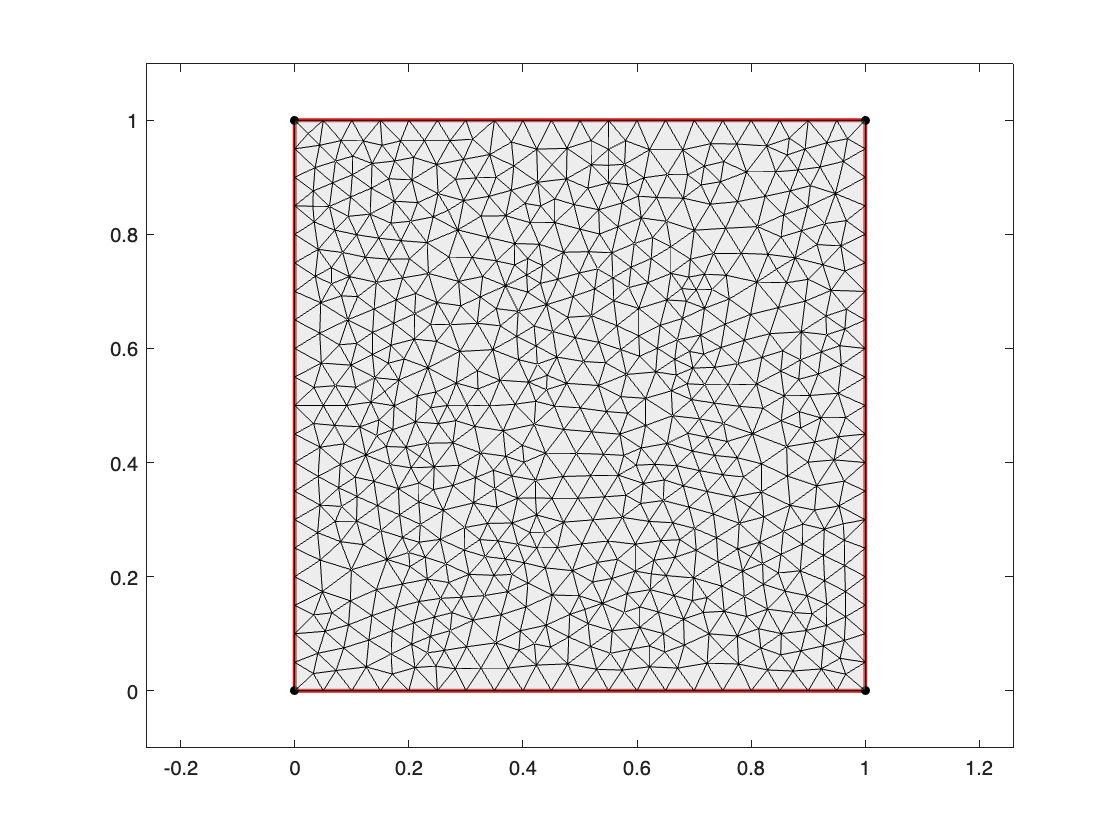

mesh.plot;

## 1. Scalar functions

You can now construct constant P0 and P1 scalar functions using the class Mesh methods mesh.P0 and mesh.P1.

### **1.1 Constant functions**

uP0 = mesh.P0(3);
uP1 = mesh.P1(3);

### **1.2 Functions defined from an expression in x and y**

Write as an expression containting variable names x and y as input:

uP0 = mesh.P0('sin(2*pi*x).*sin(2*pi*y)');
uP1 = mesh.P1('sin(2*pi*x).*sin(2*pi*y)');

### **1.3 Functions defined from a two variables handle function**

Defines a handle function of two variables and use it as an input 

f = @(x,y) sin(2*pi*x).*sin(2*pi*y);
uP0 = mesh.P0(f);
uP1 = mesh.P1(f);

### 1.4 Function plots

- using mesh.surf:

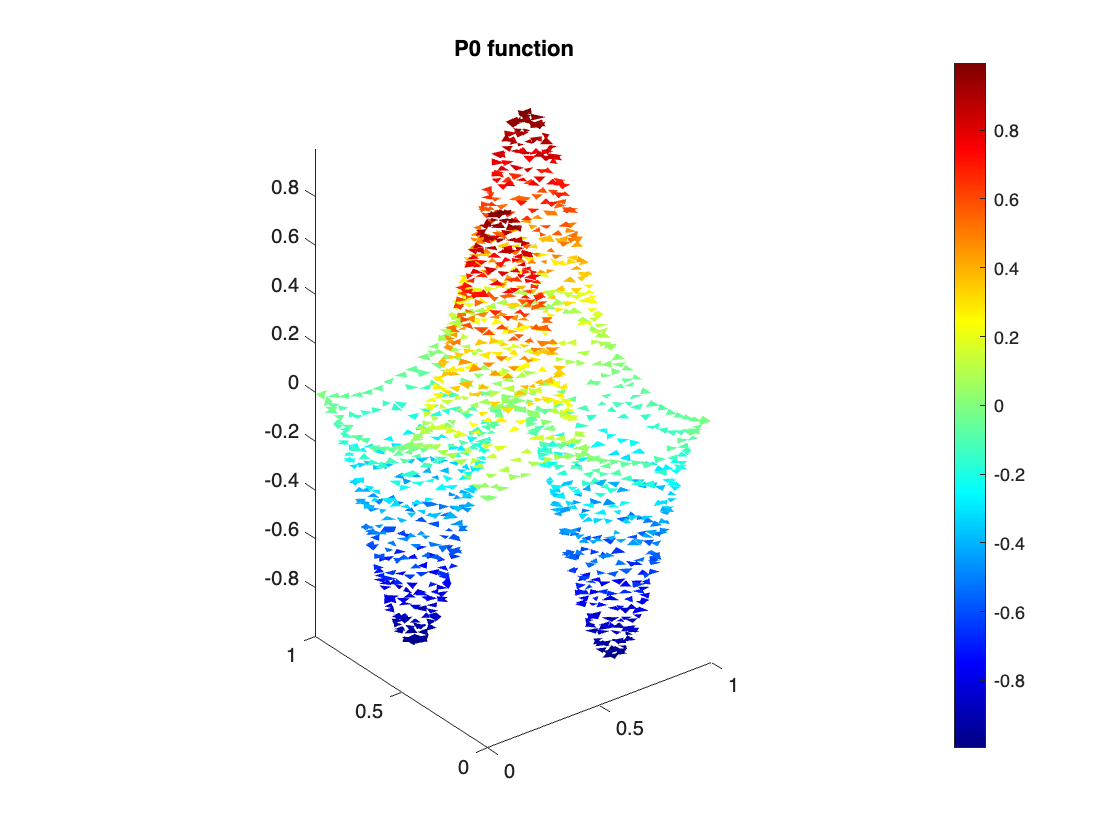

mesh.surf(uP0);
title('P0 function')

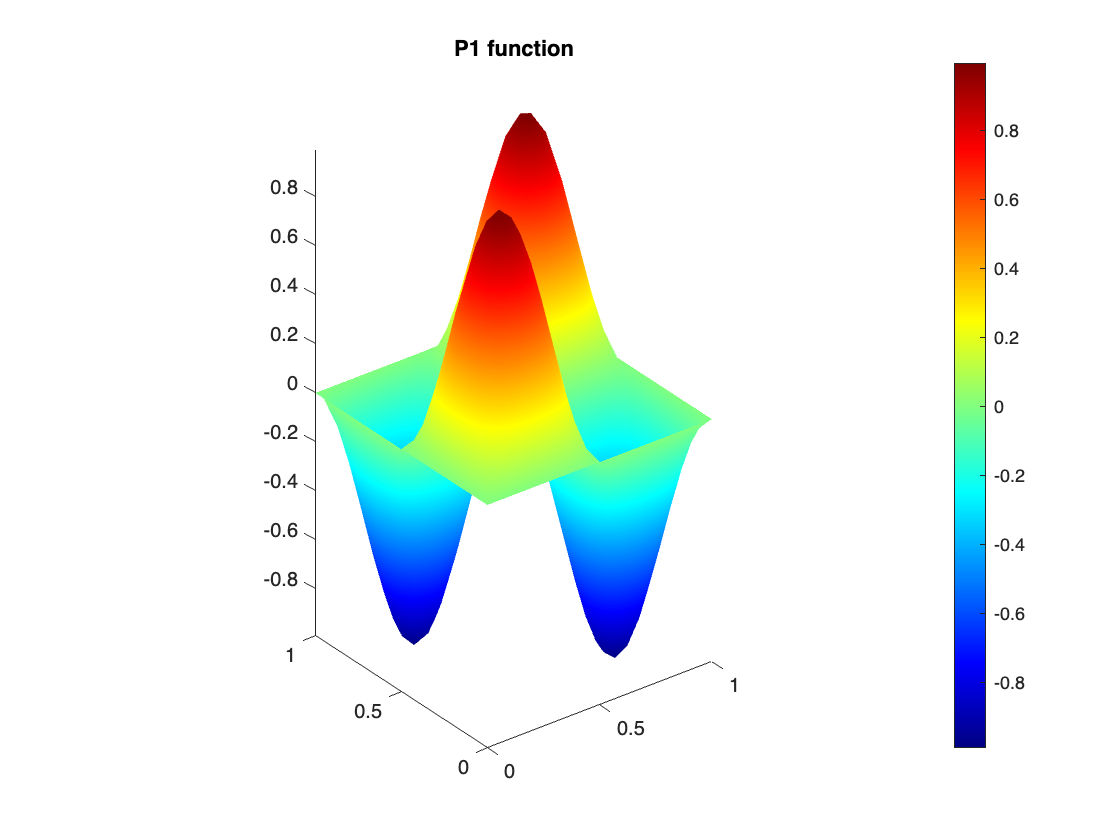

mesh.surf(uP1);
title('P1 function')
axis image

- using mesh.image

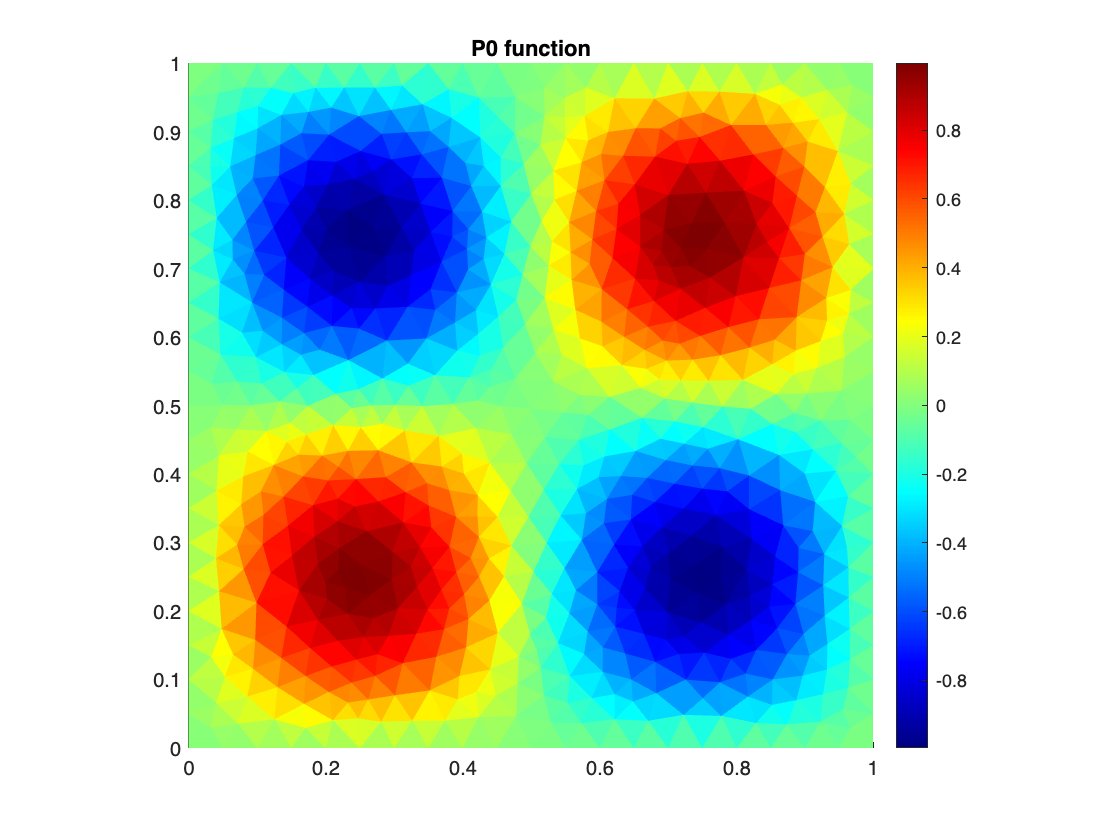

mesh.image(uP0);
title('P0 function')

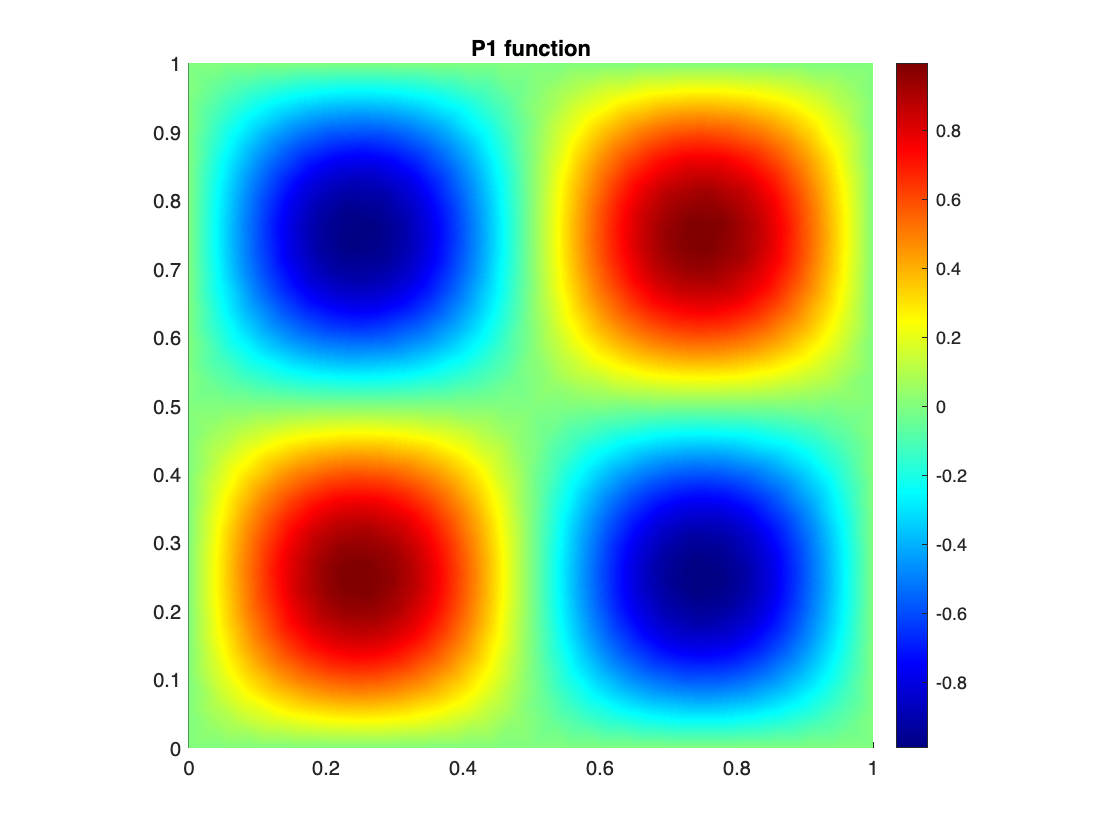

mesh.image(uP1);
title('P1 function')

### 1.5 Complex valued functions

A function can have complex values:

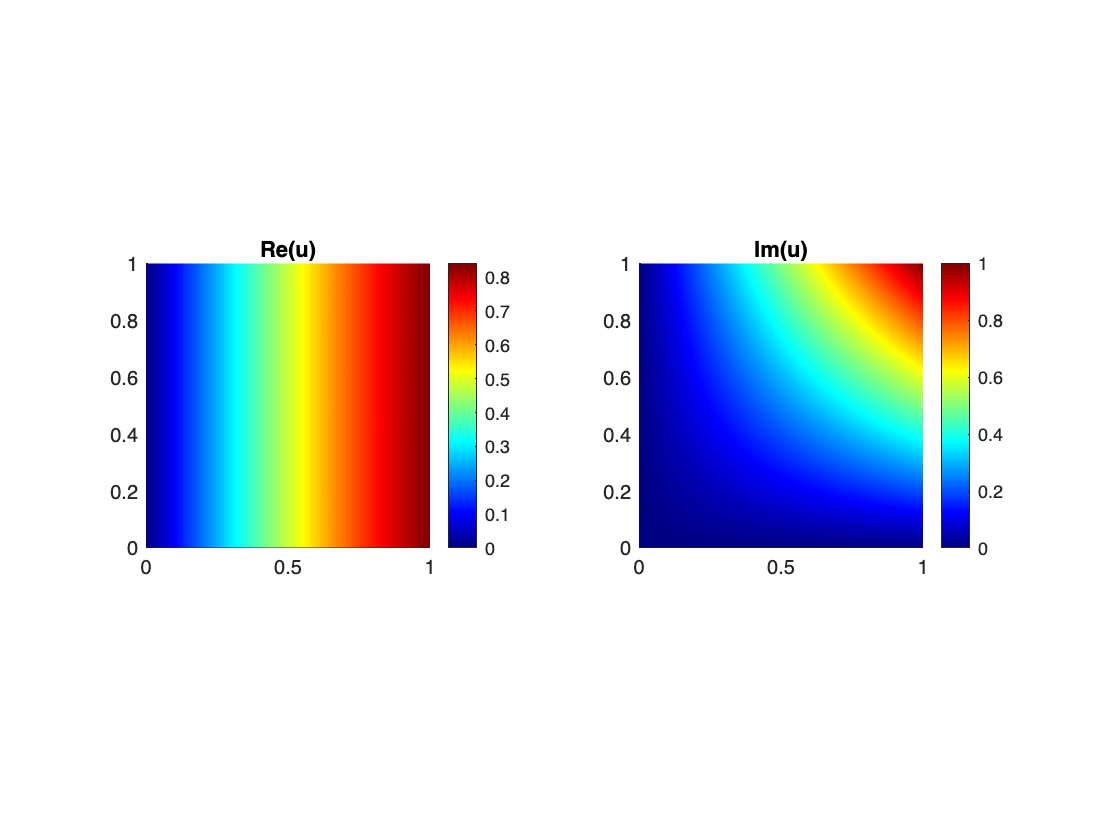

u = mesh.P1('sin(x) + 1i*x.*y');
mesh.image(u)

## 2. Vector fields

A vector field is defined using the class Mesh methods mesh.P0 and mesh.P1. 

### 2.1 Constant vector fields

v = mesh.P0(1,3);  % Or equivalently mesh.P0([1;3]) or mesh.P0([1 3])
mesh.image(v);

If you want to have the same colorbar for the two compenents in the plot, just fix the clim:

clim = [0 4];
mesh.image(v,clim);

If the two component are the same: you can also define it specifying the tensorial order as 1. For example,

v = mesh.P0(0,'order',1);

defines the null vector field.

### **2.2 Variable vector fields**

In the same manner than scalar functions, we can use either exmpression in x,y or hanlde functions of two variables:

v = mesh.P0('x','y');
mesh.image(v);

v = mesh.P1(@(x,y) [sin(2*pi*x) sin(2*pi*y)]);
mesh.image(v);

v = mesh.P1(3,'x.^2+y.^2');
mesh.image(v);

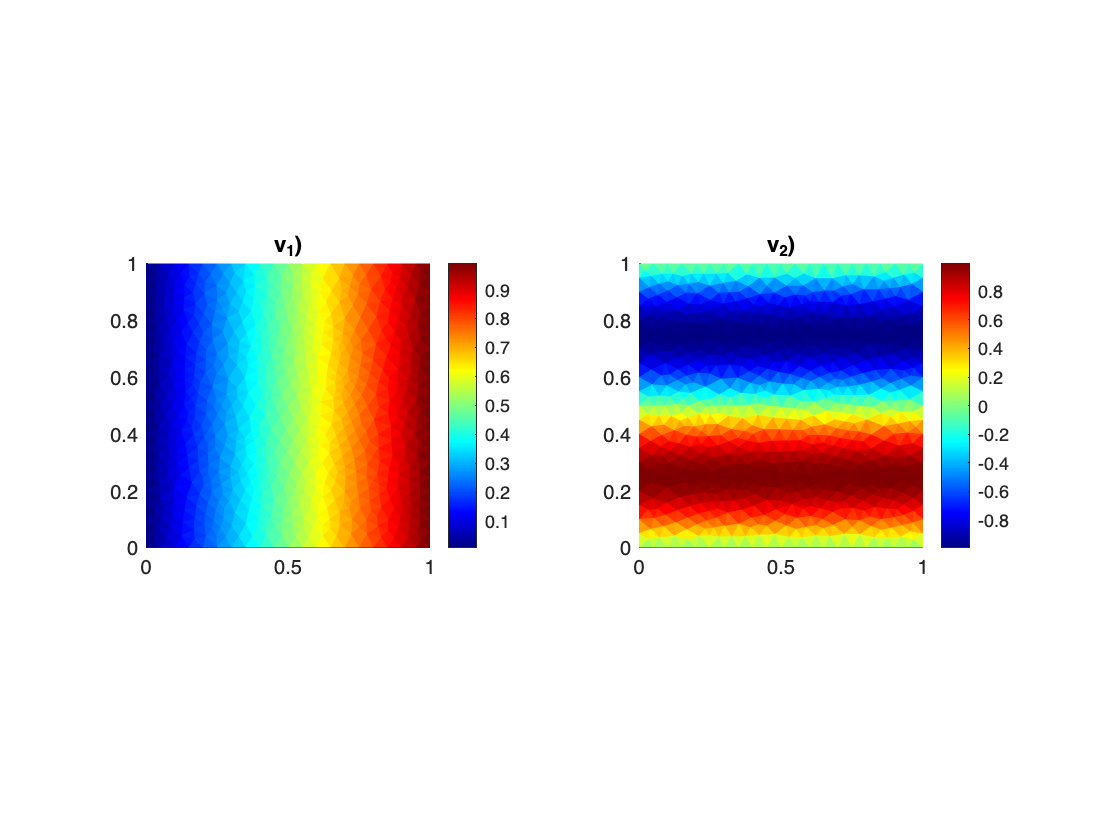

v = mesh.P0('x',@(x,y) sin(2*pi*y));
mesh.image(v);

## 3. Matrix and tensor fields

## 4. Integral calculus

You can compute the integral of any function in you domain using the Mesh method **mesh.intergal**. Input can be either a P0 or P1 function or some expression in x,y or handle function of two variables. 

u = mesh.P0('x + y');
mesh.integral(u)

ans = 1.0000

u = mesh.P1('x.*y');
mesh.integral(u)

ans = 0.2500

mesh.integral('x.^2+y.^2')

ans = 0.6667

f = @(x,y) sin(2*pi*x).*sin(2*pi*y);
mesh.integral(f)

ans = 1.0156e-07

Note that the integration method is of order 2 in case of a domain with curved boundaries and of order 3 in polygonal domains (exact for polynomials of degree 2).  Check the following test:

abs(mesh.integral('1') - 1)

ans = 0

abs(mesh.integral('x') - 1/2)

ans = 0

abs(mesh.integral('y') - 1/2)

ans = 5.5511e-17

abs(mesh.integral('x.^2') - 1/3)

ans = 5.5511e-17

abs(mesh.integral('y.^2') - 1/3)

ans = 1.1102e-16

abs(mesh.integral('x.*y') - 1/4)

ans = 8.3267e-17